net = importNetworkFromTensorFlow("Model/new_224");

Importing the saved model...


% net = importNetworkFromTensorFlow("Model/new_224_grad_attention");
I = imread("data_3dsar_pass1_az001_VV.bmp");
% I = imread("data_3dsar_pass1_az003_HV.bmp");
classNames = ["Bad", "Good"];
netInputSize = net.Layers(1).InputSize;
if size(netInputSize, 2) == 4
    I = imresize(I,netInputSize(2:3));
    I = reshape(I,[1,224,224,3]);
    I_dlarray = dlarray(single(I),'UUUU');

else
    I = imresize(I,netInputSize(1:2));
    I_dlarray = dlarray(single(I),'SSC');
end
I_dlarray = I_dlarray ./ 255;
prob = predict(net, I_dlarray)

prob =   2(C) × 1(B) single dlarray

    0.0000
    1.0000


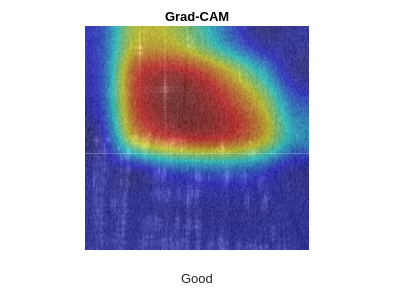

Y = scores2label(prob, classNames);
channel = find(Y == categorical(classNames));
map = gradCAM(net, I_dlarray, channel);
imshow(I);
hold on;
xlabel(Y);
imagesc(map, "AlphaData", 0.5);
colormap jet
hold off;
title("Grad-CAM");


I = imread("data_3dsar_pass1_az003_HV.bmp");
classNames = ["Bad", "Good"];
netInputSize = net.Layers(1).InputSize;
if size(netInputSize, 2) == 4
    I = imresize(I,netInputSize(1:3));
    I_dlarray = dlarray(single(I),'UUUU');
else
    I = imresize(I,netInputSize(1:2));
    I_dlarray = dlarray(single(I),'SSC');
end
I_dlarray = I_dlarray ./ 255;
prob = predict(net, I_dlarray)

prob =   2(C) × 1(B) single dlarray

    1.0000
    0.0000


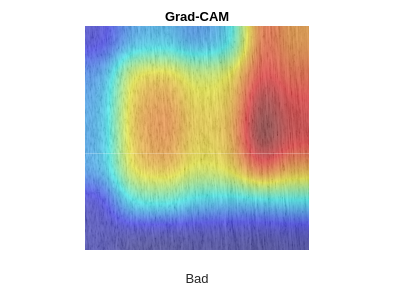

Y = scores2label(prob, classNames);
channel = find(Y == categorical(classNames));
map = gradCAM(net, I_dlarray, channel);
imshow(I);
hold on;
xlabel(Y);
imagesc(map, "AlphaData", 0.5);
colormap jet
hold off;
title("Grad-CAM");


I = imread("data_3dsar_pass5_az030_HV_style_1_numPulses_117.bmp");
classNames = ["Bad", "Good"];
netInputSize = net.Layers(1).InputSize;
if size(netInputSize, 2) == 4
    I = imresize(I,netInputSize(1:3));
    I_dlarray = dlarray(single(I),'UUUU');
else
    I = imresize(I,netInputSize(1:2));
    I_dlarray = dlarray(single(I),'SSC');
end
I_dlarray = I_dlarray ./ 255;
prob = predict(net, I_dlarray)

prob =   2(C) × 1(B) single dlarray

    1.0000
    0.0000


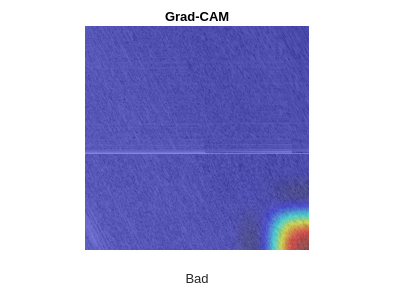

Y = scores2label(prob, classNames);
channel = find(Y == categorical(classNames));
map = gradCAM(net, I_dlarray, 2);
imshow(I);
hold on;
xlabel("Good");
imagesc(map, "AlphaData", 0.5);
colormap jet
hold off;
title("Grad-CAM");


I = imread("data_3dsar_pass5_az030_VV_style_1_numPulses_117.bmp");
classNames = ["Bad", "Good"];
netInputSize = net.Layers(1).InputSize;
if size(netInputSize, 2) == 4
    I = imresize(I,netInputSize(1:3));
    I_dlarray = dlarray(single(I),'UUUU');
else
    I = imresize(I,netInputSize(1:2));
    I_dlarray = dlarray(single(I),'SSC');
end
I_dlarray = I_dlarray ./ 255;
prob = predict(net, I_dlarray)

prob =   2(C) × 1(B) single dlarray

    1.0000
    0.0000


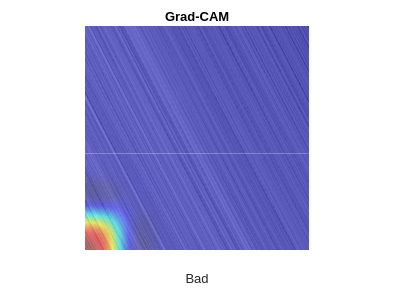

Y = scores2label(prob, classNames);
channel = find(Y == categorical(classNames));
map = gradCAM(net, I_dlarray, 2);
imshow(I);
hold on;
xlabel("Good");
imagesc(map, "AlphaData", 0.5);
colormap jet
hold off;
title("Grad-CAM");